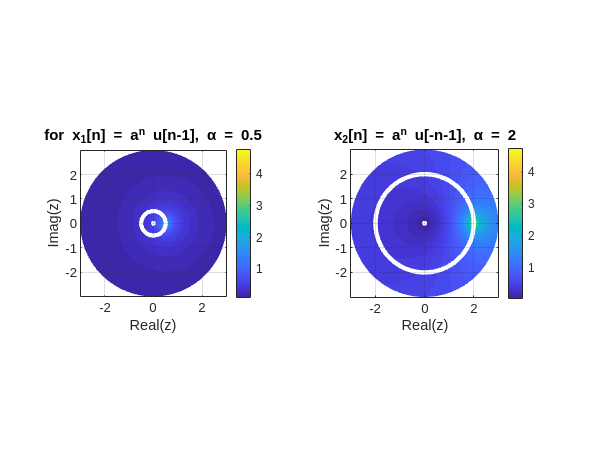

%% MATLAB Code: Z-Transform in Circular Form
clear; clc; close all;

%% Define Parameters
alpha1 = 0.5;  % For x1[n], choose |alpha| < 1
alpha2 = 2;    % For x2[n], choose |alpha| > 1

% Create a circular grid in the complex z-plane
theta = linspace(-pi, pi, 400);  % Angle from -pi to pi
r_vals = linspace(0.1, 3, 400);  % Radius values
[Theta, R] = meshgrid(theta, r_vals);
Z = R .* exp(1j * Theta);  % Convert to complex z-plane

% Compute magnitude of Z-transforms
X1_z = alpha1 ./ (Z - alpha1);  % Right-sided Z-transform
magX1 = abs(X1_z);

X2_z = Z ./ (alpha2 - Z);  % Left-sided Z-transform
magX2 = abs(X2_z);

%% Plot |X(z)| in Circular Form
figure;

% |X1(z)|
subplot(1,2,1);
contourf(R .* cos(Theta), R .* sin(Theta), log(1 + magX1), 50, 'LineColor', 'none');
colorbar;
title('for x_1[n] = a^n u[n-1], α = 0.5');
xlabel('Real(z)'); ylabel('Imag(z)');
axis equal; grid on;
hold on;
viscircles([0,0], abs(alpha1), 'LineStyle', '--', 'Color', 'w'); % Draw pole location

% |X2(z)|
subplot(1,2,2);
contourf(R .* cos(Theta), R .* sin(Theta), log(1 + magX2), 50, 'LineColor', 'none');
colorbar;
title('x_2[n] = a^n u[-n-1], α = 2');
xlabel('Real(z)'); ylabel('Imag(z)');
axis equal; grid on;
hold on;
viscircles([0,0], abs(alpha2), 'LineStyle', '--', 'Color', 'w'); % Draw pole location

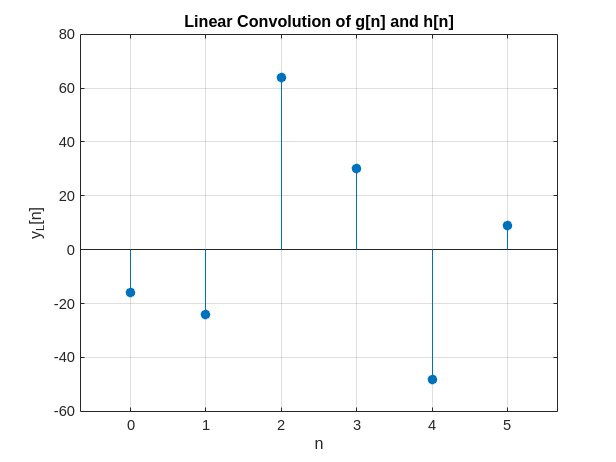

% Define sequences g[n] and h[n]
g = [2, 4, -3];      % g[n] for 0 ≤ n ≤ 2
h = [-8, 4, 12, -3]; % h[n] for 0 ≤ n ≤ 3

% Perform linear convolution
y_L = conv(g, h);

% Generate the corresponding n values
n = 0:length(y_L)-1;

% Plot the result
figure;
stem(n, y_L, 'filled');
xlabel('n');
ylabel('y_L[n]');
title('Linear Convolution of g[n] and h[n]');
grid on;